# Second Order GLM

close all;clear;clc;
% rng('default')
addpath models\
addpath utils\
load("data/rat_010_07_04_selected.mat")

## Grid Search

H=20 will cause memory overflow.

xi 0.01~5 all fine. Best xi vary from H, take 0.05.

alpha still seems no need.

1/40...Lval=-5594.0158
2/40...Lval=-5533.1264
3/40...Lval=-5537.3985
4/40...Lval=-5537.5736
5/40...Lval=-5537.5736
6/40...Lval=-5537.5736
7/40...Lval=-5537.5736
8/40...Lval=-5537.5736
9/40...Lval=-5537.5736
10/40...Lval=-5537.5736
11/40...Lval=-5537.5736


12/40:Train Complete...L:-5537.5736	...H:1	...xi:0.05	...alpha:0
      Test Complete...L:-5550.4566	...DBR:0.5233
1/40...Lval=-5650.7764
2/40...Lval=-5657.6333
3/40...Lval=-5695.4158
4/40...Lval=-5699.669
5/40...Lval=-5699.7683
6/40...Lval=-5699.7685
7/40...Lval=-5699.7685
8/40...Lval=-5699.7685
9/40...Lval=-5699.7685
10/40...Lval=-5699.7685
11/40...Lval=-5699.7685
12/40...Lval=-5699.7685


13/40:Train Complete...L:-5699.7685	...H:2	...xi:0.05	...alpha:0
      Test Complete...L:-5776.1129	...DBR:0.57287
1/40...Lval=-5777.1923
2/40...Lval=-5942.7406
3/40...Lval=-6092.5881
4/40...Lval=-6121.6731
5/40...Lval=-6122.9773
6/40...Lval=-6122.9849
7/40...Lval=-6122.9849
8/40...Lval=-6122.9849
9/40...Lval=-6122.9849
10/40...Lval=-6122.9849
11/40...Lval=-6122.9849
12/40...Lval=-6122.9849
13/40...Lval=-6122.9849


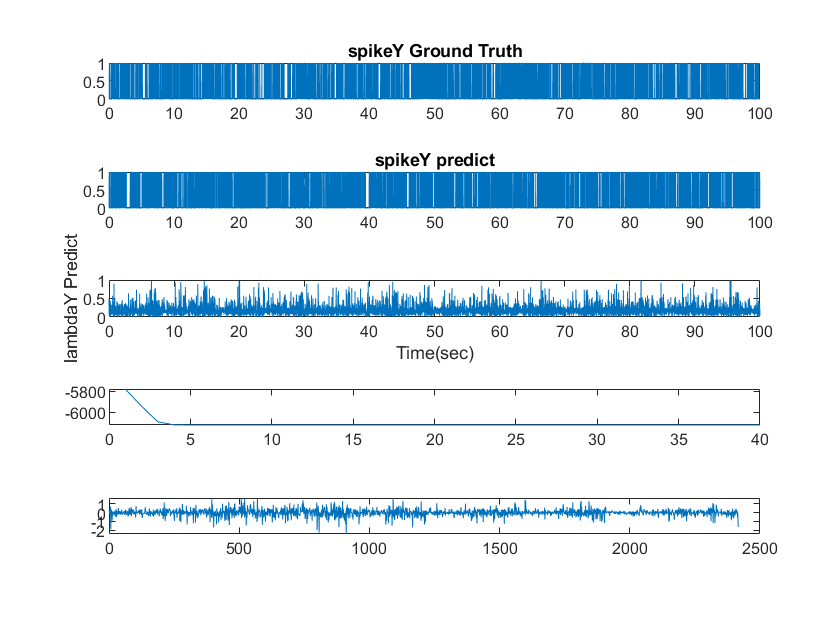

14/40:Train Complete...L:-6122.9849	...H:3	...xi:0.05	...alpha:0
      Test Complete...L:-6256.5325	...DBR:0.74639
1/40...Lval=-5943.7945
2/40...Lval=-6378.4372
3/40...Lval=-6834.6914
4/40...Lval=-7013.1391
5/40...Lval=-7040.2236
6/40...Lval=-7044.1465
7/40...Lval=-7046.7026
8/40...Lval=-7049.3199
9/40...Lval=-7052.1195
10/40...Lval=-7054.2803


GLM_sec_explore_H = struct( ...
    "H",{}, "xi",{}, "thres",{}, "iterThres",{}, ...
    "maxIter",{}, "alpha",{}, "M1Idx",{}, ...
    "W",{}, "L",{}, "DBR",{} ...
    );
for H=1:10
% H = 1; % temporal history
xi=0.05; % Weights random initial range parameter
alpha=0; % Regulization parameter
thres = 1e-3; % stop error tolerance
iterThres = 7; % stop after error over threshold $ times
maxIter = 40; % max iteration num, over needs re-initial
M1Idx = 1; % select M1 neuron
splitFun = @(history)splitDataSecOrder(mPFCspike,M1spike(:,M1Idx),history); % choose splitData function as second Order
verbose = 0;
[W, L, GLM_sec_DBR] = runGLM(H, xi, thres, iterThres, maxIter, alpha, splitFun, verbose);
  GLM_sec_explore_H(H) = struct( ...
    "H",H, "xi",xi, "thres",thres, "iterThres",iterThres, ...
    "maxIter",maxIter, "alpha",alpha, "M1Idx",M1Idx, ...
    "W",W, "L",L, "DBR",GLM_sec_DBR ...
    );
end

save("results\GLM_sec_explore_H.mat", "GLM_sec_explore_H")